# Train Self-Balancing Bicycle Using Reinforcement Learning Agents

Load the parameters of the model into the MATLAB® workspace.

config

Open Simulink Model

model = 'SimpleBikeRlAgentControl';
open_system(model)

Unable to find system or file 'SimpleBikeRlAgentControl'.

## **Create Environment Interface**

Create the observation specification.

numObs = 11;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = "observations";

Create the action specification.

numAct = 1;
actInfo = rlNumericSpec([numAct 1],LowerLimit=-1,UpperLimit=1);
actInfo.Name = "actions";

Create the environment interface for the walking robot model.

blk = model + "/RL Agent";
env = rlSimulinkEnv(model,blk,obsInfo,actInfo);
env.ResetFcn = @(in) SimplebikeResetFcn(in, ...
    path_n_points, ...
    path_max_dim, ...
    cvx_hull_n_points, ...
    [min_ref_v, max_ref_v]...
    );

## Create Agent for Training

Build the Critic Network

criticLayerSizes = [300 250];

statePath = [
    featureInputLayer(numObs,'Normalization','none','Name', 'observation')
    fullyConnectedLayer(criticLayerSizes(1), 'Name', 'CriticStateFC1', ... 
            'Weights',2/sqrt(numObs)*(rand(criticLayerSizes(1),numObs)-0.5), ...
            'Bias',2/sqrt(numObs)*(rand(criticLayerSizes(1),1)-0.5))
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticStateFC2', ...
            'Weights',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),criticLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),1)-0.5))
    ];
actionPath = [
    featureInputLayer(numAct,'Normalization','none', 'Name', 'action')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticActionFC1', ...
            'Weights',2/sqrt(numAct)*(rand(criticLayerSizes(2),numAct)-0.5), ... 
            'Bias',2/sqrt(numAct)*(rand(criticLayerSizes(2),1)-0.5))
    ];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1, 'Name', 'CriticOutput',...
            'Weights',2*5e-3*(rand(1,criticLayerSizes(2))-0.5), ...
            'Bias',2*5e-3*(rand(1,1)-0.5))
    ];

% Connect the layer graph
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

Build the Actor Network

actorLayerSizes = [300 250];
actorNetwork = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(actorLayerSizes(1), 'Name', 'ActorFC1', ...
            'Weights',2/sqrt(numObs)*(rand(actorLayerSizes(1),numObs)-0.5), ... 
            'Bias',2/sqrt(numObs)*(rand(actorLayerSizes(1),1)-0.5))
    reluLayer('Name', 'ActorRelu1')
    fullyConnectedLayer(actorLayerSizes(2), 'Name', 'ActorFC2', ... 
            'Weights',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),actorLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),1)-0.5))
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(numAct, 'Name', 'ActorFC3', ... 
                       'Weights',2*5e-3*(rand(numAct,actorLayerSizes(2))-0.5), ... 
                       'Bias',2*5e-3*(rand(numAct,1)-0.5))                       
    tanhLayer('Name','ActorTanh1')
    ];


%% Specify options for the critic and actor representations using rlOptimizerOptions
criticOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4);
actorOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

%% Create critic and actor representations using specified networks and
% options
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,'ObservationInputNames','observation','ActionInputNames','action');
actor  = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

%% Specify DDPG agent options
agentOptions = rlDDPGAgentOptions;
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = DiscountFactor;
agentOptions.MiniBatchSize = MiniBatchSize;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.TargetSmoothFactor = 5e-3;
% agentOptions.NoiseOptions.MeanAttractionConstant = 1;
% agentOptions.NoiseOptions.Variance = 0.1;
agentOptions.ActorOptimizerOptions = actorOptions;
agentOptions.CriticOptimizerOptions = criticOptions;

%% Create agent using specified actor representation, critic representation and agent options
agent = rlDDPGAgent(actor,critic,agentOptions);

## Specify Training Options

maxEpisodes = trainingMaxEpisodes;
maxSteps = floor(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxEpisodes,...
    MaxStepsPerEpisode=maxSteps,...
    ScoreAveragingWindowLength=250,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=maxEpisodes,...
    SaveAgentCriteria="EpisodeFrequency",...
    SaveAgentValue=500, ...
    SaveAgentDirectory = pwd + "\CandidateAgents");

To train the agent in parallel, specify the following training options. Training in parallel requires Parallel Computing Toolbox™. If you do not have Parallel Computing Toolbox software installed, set `UseParallel` to `false`.

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- After every 32 steps, have each worker send experiences to the parallel pool client (the MATLAB® process which starts the training). DDPG and TD3 agents require workers to send experiences to the client.

trainOpts.UseParallel = false;
% trainOpts.ParallelizationOptions.Mode = "async";
% trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
% trainOpts.ParallelizationOptions.DataToSendFromWorkers = "Experiences";

## Train Agent

Turn on the visualization of the environment during training

USE_PRE_TRAINED_MODEL = false;

% Set agent option parameter:
agentOpts.ResetExperienceBufferBeforeTraining = not(USE_PRE_TRAINED_MODEL);

% load("CandidateAgents/Agent2000.mat","agent")
set_param(model,'SimMechanicsOpenEditorOnUpdate','off');

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This process is computationally intensive and takes several hours to complete for each agent. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining `to `true`. Due to randomness in the parallel training, you can expect different training results from the plots that follow. The pretrained agents were trained in parallel using four workers.

doTraining = true;
if doTraining
    % Train the agent.8im
    trainingStats = train(agent,env,trainOpts);
end

Found algebraic loop containing: 
SimpleBikeRlAgentControl/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Dot Product1
SimpleBikeRlAgentControl/env/Config/Solver Configuration/EVAL_KEY/INPUT_4_1_1
SimpleBikeRlAgentControl/env/Config/Solver Configuration/EVAL_KEY/STATE_1
SimpleBikeRlAgentControl/env/Config/Solver Configuration/EVAL_KEY/OUTPUT_1_0


## Simulate Trained Agents

Load trained model

set_param(model,'SimMechanicsOpenEditorOnUpdate','on');
load("CandidateAgents/Agent3000.mat","agent")

Fix the random generator seed for reproducibility.

rng(3)

To validate the performance of the trained agent, simulate it within the biped robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=maxSteps);
experience = sim(env,agent,simOptions);

Found algebraic loop containing: 
SimpleBikeRlAgentControl/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Dot Product1
SimpleBikeRlAgentControl/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Trigonometric Function
SimpleBikeRlAgentControl/env/Config/Solver Configuration/EVAL_KEY/INPUT_4_1_1
SimpleBikeRlAgentControl/env/Config/Solver Configuration/EVAL_KEY/STATE_1


Plot the bike trajectory as well as the reference path.

bike_x = getElement(experience.SimulationInfo.yout, "bike_x").Values.Data

bike_x =    -0.0000
    0.0001
    0.0007
    0.0038
    0.0140
    0.0232
    0.0311
    0.0389
    0.0463
    0.0532


bike_y = getElement(experience.SimulationInfo.yout, "bike_y").Values.Data

bike_y =     0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000



path_x = getElement(experience.SimulationInfo.yout, "path_x").Values.Data

path_x =          0    2.0408    4.0816    6.1224    8.1633   10.2041   12.2449   14.2857   16.3265   18.3673   20.4082   22.4490   24.4898   26.5306   28.5714   30.6122   32.6531   34.6939   36.7347   38.7755   40.8163   42.8571   44.8980   46.9388   48.9796   51.0204   53.0612   55.1020   57.1429   59.1837   61.2245   63.2653   65.3061   67.3469   69.3878   71.4286   73.4694   75.5102   77.5510   79.5918   81.6327   83.6735   85.7143   87.7551   89.7959   91.8367   93.8776   95.9184   97.9592  100.0000


path_y = getElement(experience.SimulationInfo.yout, "path_y").Values.Data

path_y =          0    0.1087    0.2173    0.3260    0.4347    0.5433    0.6520    0.7607    0.8693    0.9780    1.0866    1.1953    1.3040    1.4126    1.5213    1.6300    1.7386    1.8473    1.9560    2.0646    2.1733    2.2820    2.3906    2.4993    2.6080    2.7166    2.8253    2.9339    3.0426    3.1513    3.2599    3.3686    3.4773    3.5859    3.6946    3.8033    3.9119    4.0206    4.1293    4.2379    4.3466    4.4553    4.5639    4.6726    4.7812    4.8899    4.9986    5.1072    5.2159    5.3246


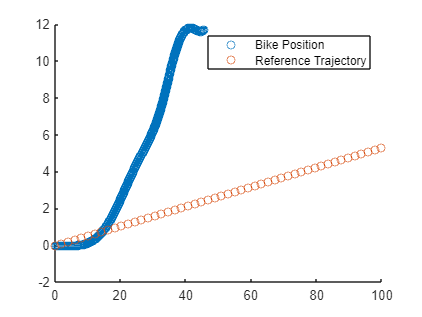


scatter(bike_x, bike_y)
hold on

scatter(path_x, path_y)
legend("Bike Position", "Reference Trajectory")
hold off

getError([bike_x(2000), bike_y(2000)], [ref_x, -ref_y])

function [cte] = getError(bike_pos, ref_path)
    % Outputs initialization (necessary for error avoidance)
    cte = 0;
    yawError = 0;
    point1_pos = zeros(2, 1);
    point2_pos = zeros(2, 1);

    % Check if there are enough points in the path
    if numel(ref_path) < 2
        error('Path must have at least two points.');
    end

    % Find the two closest points on the path
    distances = sqrt((ref_path(:, 1) - bike_pos(1)).^2 + (ref_path(:, 2) - bike_pos(2)).^2);
    [~, indices] = sort(distances);
    closest_idx = indices(1);

    %% Calculate the cross track error (distance from bike to line formed by two closest points)
    
    % Bike position
    x0 = bike_pos(1);
    y0 = bike_pos(2);

    % Closest Point Position
    x1 = ref_path(closest_idx, 1);
    y1 = ref_path(closest_idx, 2);

    % Next Path Points
    x2 = ref_path(mod(closest_idx + 1, size(ref_path, 1)) + 1, 1);
    y2 = ref_path(mod(closest_idx + 1, size(ref_path, 1)) + 1, 2);
    
    x3 = ref_path(mod(closest_idx + 2, size(ref_path, 1)) + 1, 1);
    y3 = ref_path(mod(closest_idx + 2, size(ref_path, 1)) + 1, 2);

    cte = ((x2-x1)*(y1-y0) - (x1-x0)*(y2-y1)) / sqrt((x2-x1)^2 + (y2-y1)^2);

end